# Estimation, Filtering and Detection

## Homework 3B: Current Sensor Fault

## Timur Uzakov

## MACROS

clear all;
storeFigures = false; % set true if you want to save plots

## Problem 1:

% Design healthy (m=1) state-space model
% Design faulty  (m=2) state-space model
% Find controller gain K_p to keep current limited to 200 A and no
% overshoot
% Analyze observability of m1
% Analyze observability of m2

% Motor parameters
R = 0.1;                % Ohms
L = 0.5;                % Henrys
Km = 0.5;               % motor constant
J = 10;                 % kg.m^2/s^2
Kp = 3;
% Healthy system m=1

A = [0 Km/J; -Kp/L -(R+Km)/L];
B = [0 1/J; Kp/L 0];
C = [1 0;0 1];
D = 0;
sys_healthy = ss(A,B,C,D);

% Faulty system m=2

A_f = A;
B_f = B;
C_f = [1 0;0 0];
D_f = 0;
sys_faulty = ss(A_f,B_f,C_f,D_f);

% Observability
disp("Observability of healthy system")

Observability of healthy system


Ob_healthy = obsv(A,C);
unobsv = length(A) - rank(Ob_healthy)

unobsv = 0

disp("Observability of faulty system")

Observability of faulty system


Ob_faulty = obsv(A_f,C_f);
unobsv = length(A_f) - rank(Ob_faulty)

unobsv = 0

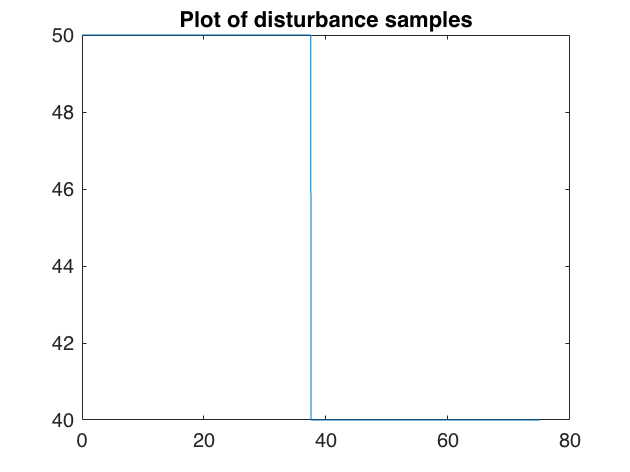




% disturbance
Ts = 0.05;
N = 1500;
T = Ts*N;
t = 0:Ts:T;
load = 50;        % Nm
deviation = 10;
Td = load*ones(1,N); % load disturbance
for i=1:N
      if i>N/2 && i<=N
         Td(i) = Td(i) - deviation;
      end
end
Td = [load Td];
figure;
plot(t,Td);
title("Plot of disturbance samples");

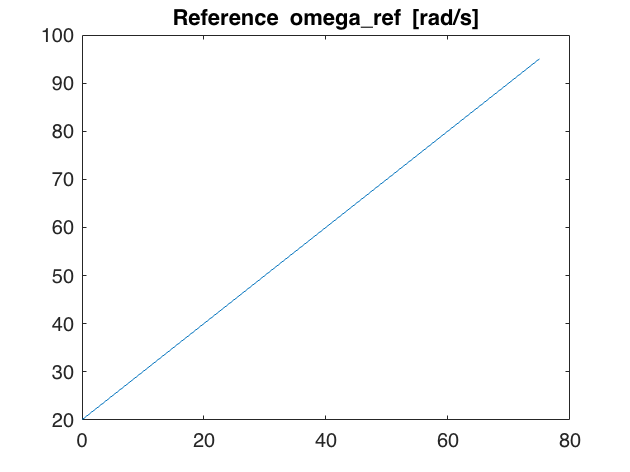


% refference signal
w_ref = 20*ones(size(t));
for i=1:length(t)
    w_ref(i) = w_ref(i) + 0.05*i;
end
figure();
plot(t,w_ref);
title("Reference omega\_ref [rad/s]");

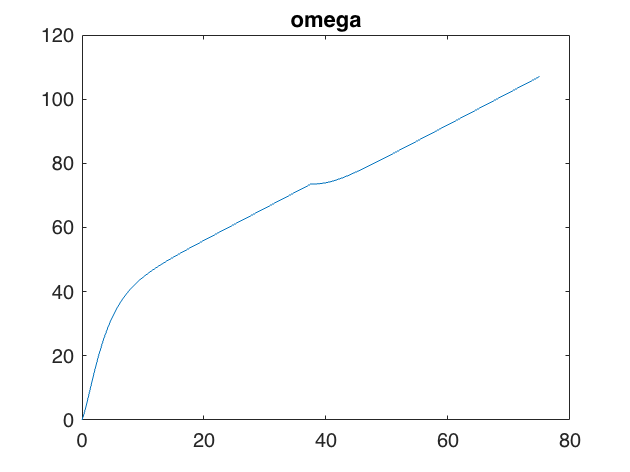


u = [w_ref;Td];
response = lsim(sys_healthy,u,t);
figure;
plot(t,response(:,1));
title("omega");

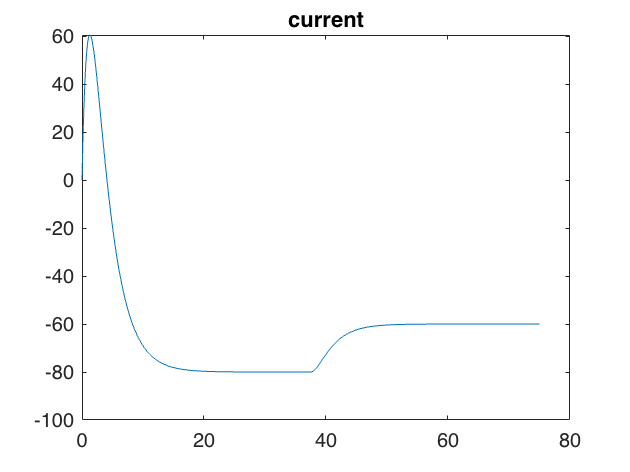

figure;
plot(t,response(:,2));
title("current");

## Problem 2:

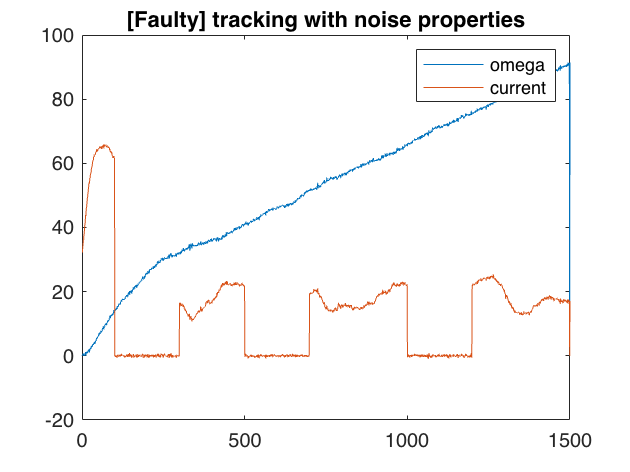

% Select and justify process noise properties
% Find input-output data with multiple sensor faults

% noise properties
Q = 0.1;
R_cov = 0.1;
etta = 1; % selected as 1 (Tc=0) for synchronous sampling purposes

% healthy
Ah = expm(A*Ts);
Bh = inv(A)*(expm(A*Ts)-expm(A*0))*B;
Ch = C*expm(A*etta*Ts);
Dh = C*inv(A)*(expm(A*etta*Ts)-expm(A*0))*B;

Qh = Q*inv(A+A')*(expm((A+A')*Ts) -expm((A+A')*0));
Sh = Q*inv(A+A')*(expm((A+A')*etta*Ts) -expm((A+A')*0))*C';
Rh = R_cov + C*Q*inv(A+A')*(expm((A+A')*etta*Ts) -expm((A+A')*0))*C';

% faulty
Af = expm(A_f*Ts);
Bf = inv(A_f)*(expm(A_f*Ts)-expm(A_f*0))*B_f;
Cf = C_f*expm(A_f*etta*Ts);
Df = C_f*inv(A_f)*(expm(A_f*etta*Ts)-expm(A_f*0))*B_f;

Qf = Q*inv(A_f+A_f')*(expm((A_f+A_f')*Ts) -expm((A_f+A_f')*0));
Sf = Q*inv(A_f+A_f')*(expm((A_f+A_f')*etta*Ts) -expm((A_f+A_f')*0))*C_f';
Rf = R_cov + C_f*Q*inv(A_f+A_f')*(expm((A_f+A_f')*etta*Ts) -expm((A_f+A_f')*0))*C_f';

Kp = 0.5;
Ki = 0.25;
Kd = 0.25;
x = zeros(2,N);
y = zeros(2,N);
integral = 0;
last_error = 0;

fault = zeros(1,N);

for i=1:(N-1)
    error = (w_ref(i) - x(1,i));
    integral = integral + error*Ts; 
    u(:,i) = [Kp*error+Ki*integral + Kd*(error - last_error)/Ts;0];
    if ((i>100) && (i<300))||((i>500) && (i<700))||((i>1000) && (i<1200))
        % faulty
        x(:,i+1) = Af*x(:,i) + Bf*u(:,i) + sqrtm(Qh)*randn(2, 1);
        y(:,i)   = Cf*x(:,i) + Df*u(:,i) + sqrtm(Rh)*randn(2, 1);
        fault(i) = 1;
    else
        % normal
        x(:,i+1) = Ah*x(:,i) + Bh*u(:,i) + sqrtm(Qf)*randn(2, 1);
        y(:,i)   = Ch*x(:,i) + Dh*u(:,i) + sqrtm(Rf)*randn(2, 1);
        fault(i) = 0;
    end
    last_error = error;
end
y(:,end+1) = Ch*x(:,N) + Dh*u(:,N) + sqrtm(Rf)*randn(2, 1);
fault(end+1) = 0;

figure();
plot(y(1,:));
hold on
plot(y(2,:));
legend("omega","current")
title("[Faulty] tracking with noise properties")
hold off

## Problem 3:

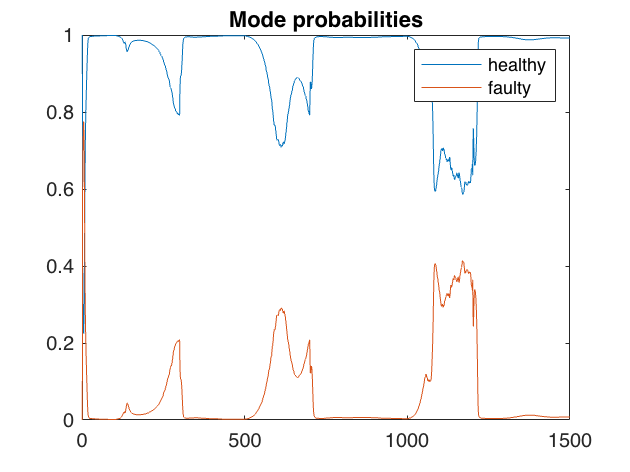

% Design IMM algorithm
% Evaluate unmeasurable load
% Detect faults of current sensor
% p12 = 0.001 transition to fault
% p21 = 0.005 recovery

x0 = [0; 0];
prob_init = [1; 0];
xhat0 = cell(2, 1);

xhat = cell(1, 2);
xhat{1} = zeros(2, N);
xhat{2} = zeros(2, N);
xhat{1}(:, 1) = x0;
xhat{2}(:, 1) = x0;

xhatc = zeros(2, N);
xTLoad = zeros(1, N);
xTLoad(1) = 0;
H = cell(2, 1);
H{1} = Ch;
H{2} = Cf;

P = cell(2, N);
P{1,1} = Qh;
P{2,1} = Qf;

Qc = cell(2, 1);
Qc{1} = Qh;
Qc{2} = Qf;

Rc = cell(2, 1);
Rc{1} = Rh;
Rc{2} = Rf;

prob_vec = zeros(2, N);
prob_vec(:, 1) = prob_init;
Lk = cell(2, N);
Sk = cell(2, N);

r = cell(2, N);
W = cell(2, N);

% Interaction
Pt = [0.999, 0.001; 
      0.005, 0.995];

mu = [1;0];
% Normalization
transfer_1 = [Pt(1,1)*mu(1)/(Pt(1,1)*mu(1)+Pt(2,1)*mu(2));Pt(2,1)*mu(1)/(Pt(1,1)*mu(1)+Pt(2,1)*mu(2))];
transfer_2 = [Pt(1,2)*mu(2)/(Pt(1,2)*mu(1)+Pt(2,2)*mu(2));Pt(2,2)*mu(2)/(Pt(1,2)*mu(1)+Pt(2,2)*mu(2))];
for i = 2:N
    % filter 1 init state
    % transfer prob became nan after 2nd iteration
    xhat0{1} = xhat{1}(:, i-1)*transfer_1(1) + xhat{2}(:, i-1)*transfer_1(2);
    % filter 2 init state
    xhat0{2} = xhat{1}(:, i-1)*transfer_2(1) + xhat{2}(:, i-1)*transfer_2(2);
    
    
    % filter 1 init cov
    P0{1} = (P{1, i-1} + (xhat{1}(:, i-1) - xhat0{1})*(xhat{1}(:, i-1) - xhat0{1})')*transfer_1(1) + ...
            (P{2, i-1} + (xhat{2}(:, i-1) - xhat0{1})*(xhat{2}(:, i-1) - xhat0{1})')*transfer_1(2);
    
    % filter 2 init cov
    P0{2} = (P{1, i-1} + (xhat{1}(:, i-1) - xhat0{2})*(xhat{1}(:, i-1) - xhat0{2})')*transfer_2(1) + ...
            (P{2, i-1} + (xhat{2}(:, i-1) - xhat0{2})*(xhat{2}(:, i-1) - xhat0{2})')*transfer_2(2);

    % Filtering
    % Prediction step
    % filter 1
    xhat{1}(:, i) = Ah*xhat0{1} + Bh*u(:,i-1);
    % filter 2
    xhat{2}(:, i) = Af*xhat0{2} + Bf*u(:,i-1);
    
    %% filter 1
    P{1, i} = Ah*P0{1}*Ah' + Qc{1};
    %% filter 2
    P{2, i} = Af*P0{2}*Af' + Qc{2};
    
    % Correction step
    % innovation
    r{1, i} = y(:,i) - H{1}*xhat{1}(:, i);
    r{2, i} = y(:,i) - H{2}*xhat{2}(:, i);

    % residual covariance
    Sk{1, i} = H{1}*P{1, i}*H{1}' + Rc{1};
    Sk{2, i} = H{2}*P{2, i}*H{2}' + Rc{2};
    
    % Kalman gain
    W{1, i} = P{1, i}*H{1}'/(Sk{1, i});
    W{2, i} = P{2, i}*H{2}'/(Sk{2, i});

    % update
    xhat{1}(:, i) = xhat{1}(:, i) + W{1, i}*r{1, i};
    xhat{2}(:, i) = xhat{2}(:, i) + W{2, i}*r{2, i};
    
    P{1, i} = P{1, i} - W{1, i}*H{1}*P{1, i};
    P{2, i} = P{2, i} - W{2, i}*H{2}*P{2, i};
    
    % Likelihood update

    factor1 = 1/(det(P{1,i}));
    factor2 = 1/(det(P{2,i}));
    total = factor1+factor2;
    prob1 = factor1/total;
    prob2 = factor2/total;


    mu = [prob1 prob2];
    transfer_1 = [Pt(1,1)*mu(1)/(Pt(1,1)*mu(1)+Pt(2,1)*mu(2));Pt(2,1)*mu(1)/(Pt(1,1)*mu(1)+Pt(2,1)*mu(2))];
    transfer_2 = [Pt(1,2)*mu(2)/(Pt(1,2)*mu(1)+Pt(2,2)*mu(2));Pt(2,2)*mu(2)/(Pt(1,2)*mu(1)+Pt(2,2)*mu(2))];
    % Combination of two filters
    prob_vec(:, i) = mu;
    
    xhatc(:, i) = xhat{1}(:, i)*prob1 + xhat{2}(:, i)*prob2;
    Pc{i} = (P{1, i} + (xhat{1}(:, i) - xhatc(:, i))*(xhat{1}(:, i) - xhatc(:, i))')*prob1 + ...
            (P{2, i} + (xhat{2}(:, i) - xhatc(:, i))*(xhat{2}(:, i) - xhatc(:, i))')*prob2;  
    xTLoad(i) = (xhatc(1,i)-xhatc(1,i-1))*J - Km*xhatc(2,i);
end


figure;
plot(prob_vec(1,:));
hold on
plot(prob_vec(2,:));
title("Mode probabilities");
legend("healthy","faulty");
hold off

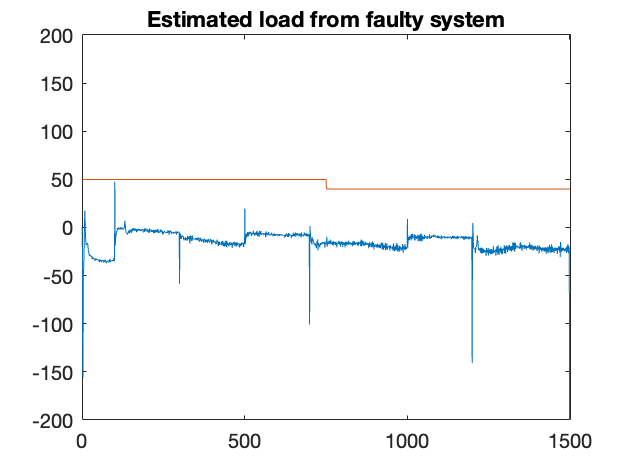


figure;
plot(xTLoad);
hold on
plot(Td)
title("Estimated load from faulty system");
ylim([-200 200])

## Problem 3.2:

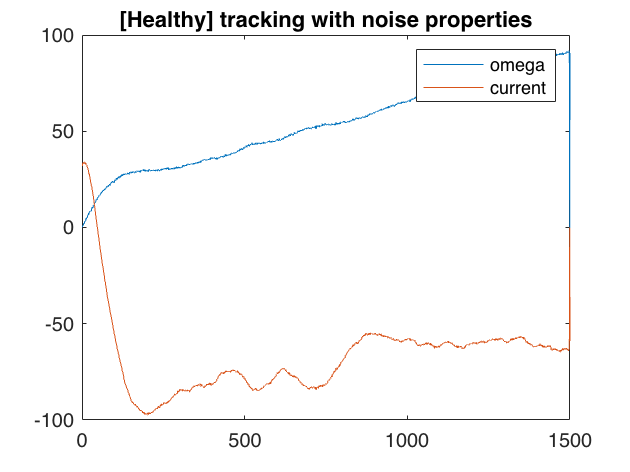

% Estimation of load
% Design without faults
% noise properties
Q = 0.0001;
R_cov = 0.1;
etta = 1; % selected as 1 (Tc=0) for synchronous sampling purposes

% healthy
Ah = expm(A*Ts);
Bh = inv(A)*(expm(A*Ts)-expm(A*0))*B;
Ch = C*expm(A*etta*Ts);
Dh = C*inv(A)*(expm(A*etta*Ts)-expm(A*0))*B;

Qh = Q*inv(A+A')*(expm((A+A')*Ts) -expm((A+A')*0));
Sh = Q*inv(A+A')*(expm((A+A')*etta*Ts) -expm((A+A')*0))*C';
Rh = R_cov + C*Q*inv(A+A')*(expm((A+A')*etta*Ts) -expm((A+A')*0))*C';

Kp = 0.5;
Ki = 0.25;
Kd = 0.25;
x = zeros(2,N);
y = zeros(2,N);
integral = 0;
last_error = 0;

fault = zeros(1,N);

for i=1:(N-1)
    error = (w_ref(i) - x(1,i));
    integral = integral + error*Ts; 
    u(:,i) = [Kp*error+Ki*integral + Kd*(error - last_error)/Ts;Td(i)];
    % normal
    x(:,i+1) = Ah*x(:,i) + Bh*u(:,i) + sqrtm(Qf)*randn(2, 1);
    y(:,i)   = Ch*x(:,i) + Dh*u(:,i) + sqrtm(Rf)*randn(2, 1);
    fault(i) = 0;
    last_error = error;
end
y(:,end+1) = Ch*x(:,N) + Dh*u(:,N) + sqrtm(Rf)*randn(2, 1);
fault(end+1) = 0;

figure();
plot(y(1,:));
hold on
plot(y(2,:));
legend("omega","current")
title("[Healthy] tracking with noise properties")
hold off

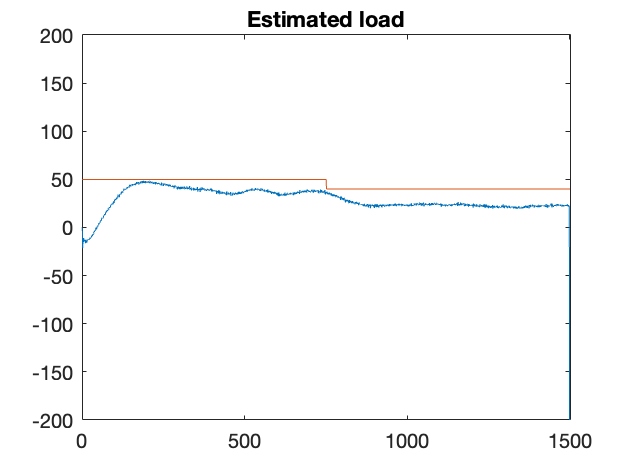



x0 = [0; 0];
prob_init = [1; 0];
xhat0 = cell(2, 1);

xhat = cell(1, 2);
xhat{1} = zeros(2, N);
xhat{2} = zeros(2, N);
xhat{1}(:, 1) = x0;
xhat{2}(:, 1) = x0;

xhatc = zeros(2, N);
xTLoad = zeros(1, N);
xTLoad(1) = 0;
H = cell(2, 1);
H{1} = Ch;
H{2} = Cf;

P = cell(2, N);
P{1,1} = Qh;
P{2,1} = Qf;

Qc = cell(2, 1);
Qc{1} = Qh;
Qc{2} = Qf;

Rc = cell(2, 1);
Rc{1} = Rh;
Rc{2} = Rf;

prob_vec = zeros(2, N);
prob_vec(:, 1) = prob_init;
Lk = cell(2, N);
Sk = cell(2, N);

r = cell(2, N);
W = cell(2, N);

for i = 2:N
    % filter 1 init state
    xhat0{1} = xhat{1}(:, i-1);
    
    
    % filter 1 init cov
    P0{1} = P{1, i-1};

    % Filtering
    % Prediction step
    % filter 1
    xhat{1}(:, i) = Ah*xhat0{1} + Bh*u(:,i-1);
    
    %% filter 1
    P{1, i} = Ah*P0{1}*Ah' + Qc{1};
    
    % Correction step
    % innovation
    r{1, i} = y(:,i) - H{1}*xhat{1}(:, i);
    % residual covariance
    Sk{1, i} = H{1}*P{1, i}*H{1}' + Rc{1};
    % Kalman gain
    W{1, i} = P{1, i}*H{1}'/(Sk{1, i});
    % update
    xhat{1}(:, i) = xhat{1}(:, i) + W{1, i}*r{1, i}; 
    P{1, i} = P{1, i} - W{1, i}*H{1}*P{1, i};

    xTLoad(i) = (xhat{1}(1,i)-xhat{1}(1,i-1))*J - Km*xhat{1}(2,i);
end

figure;
plot(xTLoad);
hold on
plot(Td)
title("Estimated load");
ylim([-200 200])

## Problem 4:

% Analyze the performance of detection
% Compare IMM to KF using only rotation speed sensor
% Is it possible to jsutify use of current sensor?

## Problem 5:

% Lessons learned

## Additional tools

% Storing figures
if storeFigures
    for i=1:10
        filename = strcat('figure_',num2str(i));
        foldername = './figures/';
        saveas(figure(i),fullfile(foldername,filename),'jpg');
    end
end